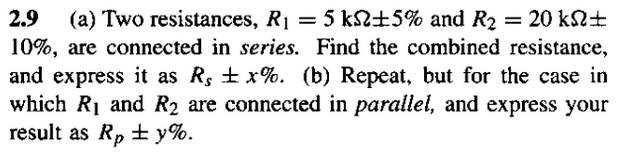

Encontramos la resistencia equivalente teniendo en cuenta sus tolerancias:

clc, clear, close all;
format short g;

r1 = 5000; %ohms
r2 = 20000; %ohms
tr1 = 0.05; %factor porcentual
tr2 = 0.10; %factor porcentual


Primero calculamos los rangos de tolerancia:

rango_r1 = r1*tr1; %ohms
rango_r2 = r2*tr2; %ohms
rango_eq = rango_r1 + rango_r2

rango_eq =         2250


Tendiendo los rangos de tolerancia calculamos la resistencia equivalente, sumando ya que estan en serie, y le añadimos el rango expresado en variacion porcentual:

r_serie = r1 + r2; %ohms
rango_porcentual = (rango_eq/r_serie)*100; % porcentaje
r_eq = [num2str(r_serie), 'Ω', ' ', num2str(rango_porcentual), '%'] % ohms porcentaje

r_eq = '25000Ω 9%'

Ahora calculamos la resistencia equivalente en paralelo

r_paralelo = 1/((1/r1) + (1/r2));
rangoeq_paralelo = 1/((1/rango_r1) + (1/rango_r2));
rango_porcentualp = (rangoeq_paralelo/r_paralelo)*100; % porcentaje
r_eqpa = [num2str(r_paralelo), 'Ω', ' ', num2str(rango_porcentualp), '%'] % ohms porcentaje

r_eqpa = '4000Ω 5.5556%'